# Performing Transfer Learning with Code

You’ve seen how to perform transfer learning by updating key layers of a pre-training network using the Deep Network Designer app.

However, if you are training many models, you likely wouldn't want to use the Deep Network Designer app every time.

In this reading, you will see how to prepare a pre-trained network for transfer learning by replacing the fully-connected and classification layers using code.

## Preparing Your Data 

We will use the fastener dataset as an example.

% Fasteners data set training folder
filename = "F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Train";
imdsFasteners = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames");

% Split into training and validation data
[imdsTrain,imdsValidation] = splitEachLabel(imdsFasteners,0.8,"randomized");

% Resize to match ResNet-18's expected input size
augTrain = augmentedImageDatastore([224,224],imdsTrain);
augVal = augmentedImageDatastore([224,224],imdsValidation);

% Set training options
opts = trainingOptions("adam","ValidationData",augVal, ...
                       "Shuffle","every-epoch", ...
                       "MiniBatchSize", 64, ...
                       "ValidationFrequency", 50, ...
                       "Plots","training-progress");

## Define the Network Architecture

We will use ResNet-18 as the basis of our architecture:

net = resnet18;

This loads a completely trained network. To adapt this network to your data, you must replace a few existing layers with new ones. 

Use the `layerGraph` function to extract the network layers and how they connect.

% Create a layer graph of the pre-trained network
lgraph = layerGraph(net);

Now that we have the layers, we can use code to replace the fully connected and classification layers with new layers with empty weight values. When you retrain the updated network, it will determine new weights for your data set.

Find the existing fully-connected layer in lgraph (for classification, it will be the third-from-last layer):

% Fully-connected layer
fcLayer = lgraph.Layers(end-2);

Each type of layer is created with its own function. You can find a list of these functions [here](https://www.mathworks.com/help/deeplearning/ug/create-simple-deep-learning-network-for-classification.html).

Create a new fully-connected layer using the `fullyConnectedLayer` function. This function takes the number of output classes and the new name for your layer as inputs.

newFCLayer = fullyConnectedLayer(19,'Name','newFC');    % 19 fastener classes

Finally, specify the layer graph to edit (`lgraph`) and replace the original fully-connected layer `fcLayer` with your new fully-connected layer `newFCLayer` with the `replaceLayer` function.

lgraph = replaceLayer(lgraph,fcLayer.Name,newFCLayer);

Repeat these steps to replace the original classification layer with a new one:

% Identify the original classification layer (the last layer in the network)
classLayer = lgraph.Layers(end);

% Create a new classification layer
newClassLayer = classificationLayer('Name','newClass');

% Replace the original layer with the new one
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Re-Train the Model with the Fastener Data

This can take some time (it took my CPU about 45 minutes). To save you some time, we have provided a copy of the final, trained model. However, we recommend running the training for at least a few iterations before canceling it to ensure it works on your computer. 

If you encounter errors, refer to `UsingAndComparingPreTrainedModels.mlx` for instructions on installing ResNet-18. If you are still encountering issues, please post to the course forums!

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |        6.25% |       39.18% |       3.7337 |       2.0632 |          0.0010 |
|       5 |          50 |       10:42:40 |       98.44% |       91.24% |       0.0589 |       0.3208 |          0.0010 |


|       9 |         100 |       10:52:03 |       98.44% |       94.85% |       0.0255 |       0.1766 |          0.0010 |
|      13 |         150 |       11:02:39 |       98.44% |       91.75% |       0.0825 |       0.3195 |          0.0010 |
|      17 |         200 |       11:12:11 |      100.00% |       97.94% |       0.0013 |       0.1206 |          0.0010 |
|      21 |         250 |       11:22:03 |      100.00% |       97.42% |       0.0009 |       0.1310 |          0.0010 |
|      25 |         300 |       11:31:40 |      100.00% |       96.39% |       0.0001 |       0.1325 |          0.0010 |
|      30 |         350 |       11:41:53 |      100.00% |       97.42% |   4.7290e-05 |       0.1259 |          0.0010 |
|      30 |         360 |       11:44:03 |      100.00% |       97.94% |       0.0001 |       0.1179 |          0.0010 |
|======================================================================================================================|
Training finished: Max epochs co

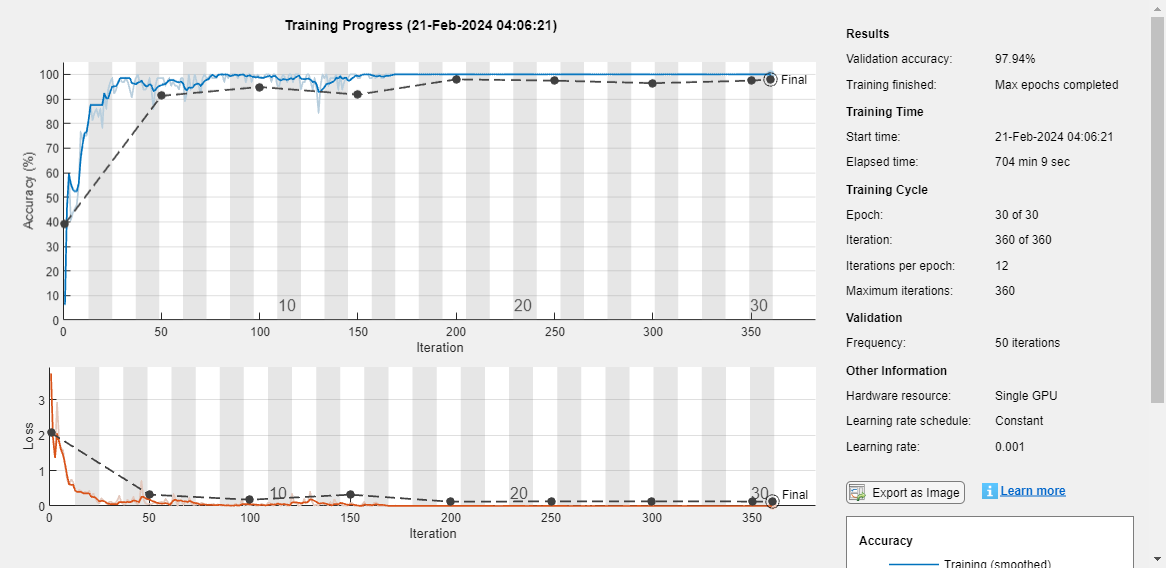

% Check the box to train a new network. Otherwise, load the trained network
% from the course files
trainNew = true;
if trainNew
    net = trainNetwork(augTrain,lgraph,opts);
else
    load fastenerResNet18Classifier.mat
end

## Evaluate Your Results

Evaluate your results using the test data:

filenameTest = "F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Test";
imdsTest = imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");

augTest = augmentedImageDatastore([224,224],imdsTest);
testPreds = classify(net,augTest);

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

testAccuracy = 0.9942

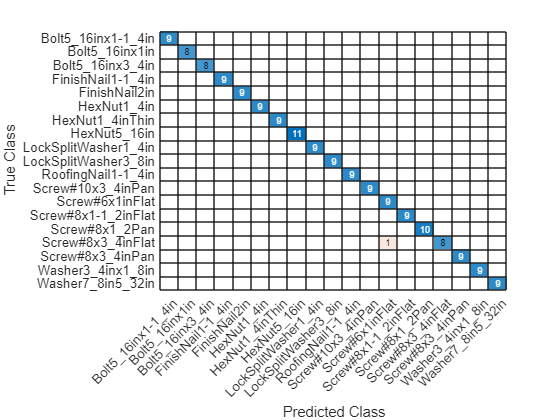

confusionchart(imdsTest.Labels,testPreds)

You likely saw significant improvement compared to the model you created from scratch in Week 1. The accuracy differences between transfer learned models and models created from scratch will vary wildly depending on the dataset, the created network, and the pre-trained network used as the basis of transfer learning. However, it’s easy to see why we recommend transfer learning for most applications.

*Copyright 2024 The MathWorks, Inc.*